## 该代码为基于BP-Adaboost的强分类器分类

%% 清空环境变量
clc
clear

%% 下载数据
load data input_train output_train input_test output_test

%% 权重初始化
[mm,nn]=size(input_train);
D(1,:)=ones(1,nn)/nn;

%% 弱分类器分类
K=10;
for i=1:K
    
    %训练样本归一化
    [inputn,inputps]=mapminmax(input_train);
    [outputn,outputps]=mapminmax(output_train);
    error(i)=0;
    
    %BP神经网络构建
    net=newff(inputn,outputn,6);
    net.trainParam.epochs=5;
    net.trainParam.lr=0.1;
    net.trainParam.goal=0.00004;
    
    %BP神经网络训练
    net=train(net,inputn,outputn);
    
    %训练数据预测
    an1=sim(net,inputn);
    test_simu1(i,:)=mapminmax('reverse',an1,outputps);
    
    %测试数据预测
    inputn_test =mapminmax('apply',input_test,inputps);
    an=sim(net,inputn_test);
    test_simu(i,:)=mapminmax('reverse',an,outputps);
    
    %统计输出效果
    kk1=find(test_simu1(i,:)>0);
    kk2=find(test_simu1(i,:)<0);
    
    aa(kk1)=1;
    aa(kk2)=-1;
    
    %统计错误样本数
    for j=1:nn
        if aa(j)~=output_train(j);
            error(i)=error(i)+D(i,j);
        end
    end
    
    %弱分类器i权重
    at(i)=0.5*log((1-error(i))/error(i));
    
    %更新D值
    for j=1:nn
        D(i+1,j)=D(i,j)*exp(-at(i)*aa(j)*test_simu1(i,j));
    end
    
    %D值归一化
    Dsum=sum(D(i+1,:));
    D(i+1,:)=D(i+1,:)/Dsum;
    
end

%% 强分类器分类结果
output=sign(at*test_simu);

%% 分类结果统计
%统计强分类器每类分类错误个数
kkk1=0;
kkk2=0;
for j=1:350
    if output(j)==1
        if output(j)~=output_test(j)
            kkk1=kkk1+1;
        end
    end
    if output(j)==-1
        if output(j)~=output_test(j)
            kkk2=kkk2+1;
        end
    end
end

kkk1

kkk1 = 0

kkk2

kkk2 = 14

disp('第一类分类错误  第二类分类错误  总错误');

第一类分类错误  第二类分类错误  总错误


% 窗口显示
disp([kkk1 kkk2 kkk1+kkk2]);

     0    14    14



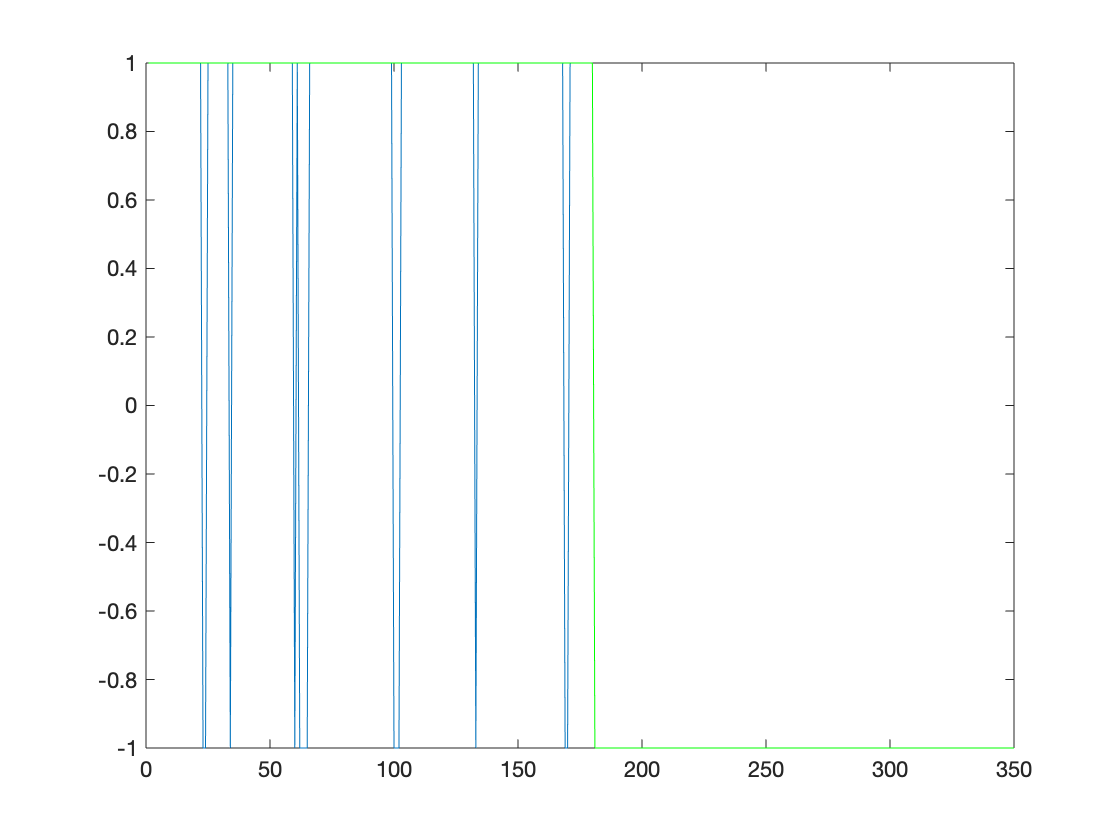


plot(output)
hold on
plot(output_test,'g')

%统计弱分离器效果
for i=1:K
    error1(i)=0;
    kk1=find(test_simu(i,:)>0);
    kk2=find(test_simu(i,:)<0);
    
    aa(kk1)=1;
    aa(kk2)=-1;
    
    for j=1:350
        if aa(j)~=output_test(j);
            error1(i)=error1(i)+1;
        end
    end
end
disp('统计弱分类器分类效果');

统计弱分类器分类效果


error1

error1 =     14    15    18    17    16    17    26    16    18    16


disp('强分类器分类误差率')

强分类器分类误差率


(kkk1+kkk2)/350

ans = 0.0400

disp('弱分类器分类误差率')

弱分类器分类误差率


(sum(error1)/(K*350))

ans = 0.0494